# Pellet Smoker: Model B

## Set Particulars

p.C_f = 500;
p.k_f = 150;
p.k_ca = 25;
p.C_c = 2500;
p.k_fa = 20;
p.gamma = 1000;
p.T_amb = 25;
p.u_p_max = 10;
p.u_p_min = 0;
p.u_f_max = 1;
p.u_f_min = 0;

## Integral Action

% initialization points
sim_params.T_c_start = p.T_amb;
sim_params.m_p_start = 10000;
% linearization and timeseries
sim_params.t_min = 0;
sim_params.t_max = 120;
sim_params.lin = linearize(p, [0.4; 0.6]);
% noise parameters
sim_params.noise_bandwidth = 100; % Hz
sim_params.noise_amplitude = 0.01; % normal to y
T_c_set_series = @(t) (t<=30)*p.T_amb+(t>30&&t<=600)*110+(t>1200)*130;
sim_params.setpoint = @(t) [Tce2Tfe(p,T_c_set_series(t)); T_c_set_series(t); 0];
sim_params.door_status = @(t) (t>=50)&&(t<20);

% Comparative simulations on integral action
[basic.t, basic.x_aug, basic.u] = run_simulation(p, sim_params, @basic_observer, @basic_feedback);
[int.t, int.x_aug, int.u] = run_simulation(p, sim_params, @integral_observer, @integral_feedback);
[sat.t, sat.x_aug, sat.u] = run_simulation(p, sim_params, @saturating_integral_observer, @integral_feedback);

figure;
plot(basic.t, basic.x_aug(2,:), 'LineWidth', 1.5); hold on;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C]']);
title('Observer Feedback with no Integral Action');
grid on;
xline(30,  '--k', ['T_c\_set=110' char(176) 'C]'],  'LabelHorizontalAlignment','right');

% plot
figure;
title("Anti-Windup Integral Action vs Saturating Integral Action")
subplot(2,1,1);
plot(int.t,   int.x_aug(2,:),   'LineWidth', 1.5); hold on;
plot(sat.t,   sat.x_aug(2,:),   'LineWidth', 1.5);
xline(30,  '--k', ['T_c\_set=110' char(176) 'C'],  'LabelHorizontalAlignment','right');
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C']);
title('T_c Comparison');
legend('integral', 'saturating integral');
grid on;
subplot(2,1,2);
plot(int.t, int.x_aug(7,:), 'LineWidth', 1.5); hold on;
plot(sat.t, sat.x_aug(7,:), 'LineWidth', 1.5);
hold off;
xlabel('Time [s]');
ylabel('x_I');
title('Integral Observer Comparison');
legend('integral', 'saturating integral');
grid on;

## Disturbance Rejection (Comparitive SS and Classical)

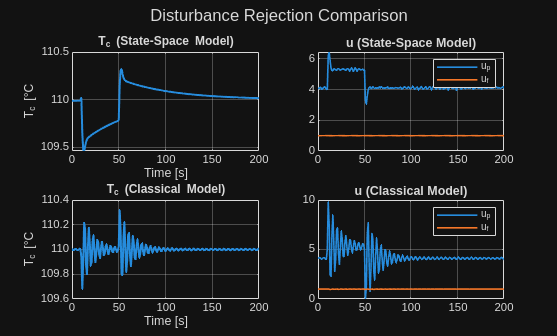

% initialization points
sim_params.T_c_start = 110;
sim_params.m_p_start = 10000;
% linearization and timeseries
sim_params.t_min = -200;
sim_params.t_max = 200;
sim_params.time_resolution = 1;
sim_params.lin = linearize(p, [0.4; 0.6]);
% noise parameters
sim_params.noise_bandwidth = 100; % Hz (noise sampling rate)
sim_params.noise_amplitude = 0; % normal to y
T_c_set_series = @(t) 110;
sim_params.setpoint = @(t) [Tce2Tfe(p,T_c_set_series(t)); T_c_set_series(t); 0];
sim_params.door_status = @(t) (t>=10)&&(t<50);
sim_params.precomp = @(p, setpoint) [0;1];
sim_params.input = @(t) t<0; % none

% Simulation for Disturbance Rejection
[ss.t, ss.x_aug, ss.u] = run_simulation(p, sim_params, @saturating_integral_observer, @integral_feedback);
[cl.t, cl.x_aug, cl.u] = run_simulation(p, sim_params, @saturating_integral_only, @PI_feedback);

% ss
figure;
sgtitle("Disturbance Rejection Comparison")
subplot(2,2,1);
plot(ss.t,   ss.x_aug(2,:),   'LineWidth', 1.5); hold on;
%set = T_c_set_series(ss.t);
%h2 = plot(ss.t,set,   'LineWidth', 1.5, 'LineStyle', ':');
%uistack(h2, 'bottom');
%legend('T_c')
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C']);
title('T_c (State-Space Model)');
%yticks([10 50 90 130]);
xlim([0 sim_params.t_max])
grid on;
subplot(2,2,2);
plot(ss.t, ss.u(1,:), 'LineWidth', 1.2); hold on;
plot(ss.t, ss.u(2,:), 'LineWidth', 1.2);
title('u (State-Space Model)');
legend('u_p','u_f');
xlim([0 sim_params.t_max])
grid on;

% cl
subplot(2,2,3);
plot(cl.t,   cl.x_aug(2,:),   'LineWidth', 1.5); hold on;
%set = T_c_set_series(cl.t);
%h2 = plot(cl.t,set,   'LineWidth', 1.5, 'LineStyle', ':');
%uistack(h2, 'bottom');
%legend('T_c')
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C']);
title('T_c (Classical Model)');
%yticks([10 50 90 130]);
xlim([0 sim_params.t_max])
grid on;
subplot(2,2,4);
plot(cl.t, cl.u(1,:), 'LineWidth', 1.2); hold on;
plot(cl.t, cl.u(2,:), 'LineWidth', 1.2);
title('u (Classical Model)');
legend('u_p','u_f');
xlim([0 sim_params.t_max])
grid on;

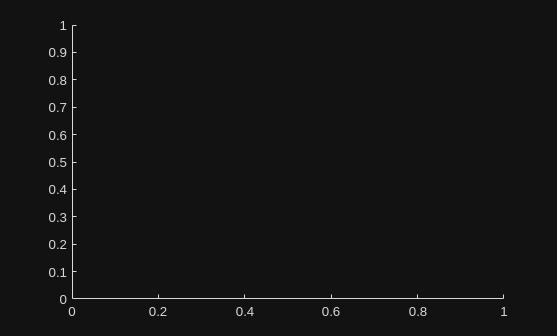



figure;
hold on;

plot(clb.t,   clb.x_aug(2,:),   'LineWidth', 1.5);

Unable to resolve the name 'clb.t'.

plot(cl.t,   cl.x_aug(2,:),   'LineWidth', 1.5, 'Color', '#E09060'); hold on;
%set = T_c_set_series(ss.t);
%h2 = plot(ss.t,set,   'LineWidth', 1.5, 'LineStyle', ':');
%uistack(h2, 'bottom');
%legend('T_c')
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C']);
title('Critical Kp Instability (Disturbance 10<t<50)');
%yticks([10 50 90 130]);
xlim([0 sim_params.t_max])
ylim([109.4 110.6])
yticks(109.5:0.25:110.5)
legend('Kp=10', 'Kp=9')
grid on;

## Profile Tracking (Comparitive SS and Classical)

% initialization points
sim_params.T_c_start = p.T_amb;
sim_params.m_p_start = 10000;
% linearization and timeseries
sim_params.t_min = 0;
sim_params.t_max = 1800;
sim_params.time_resolution = 1;
sim_params.lin = linearize(p, [0.4; 0.6]);
% noise parameters
sim_params.noise_bandwidth = 100; % Hz
sim_params.noise_amplitude = 0.01; % normal to y
T_c_set_series = @(t) (t<=600)*90+((t>600).*(t<=1200))*110+(t>1200)*130;
sim_params.setpoint = @(t) [Tce2Tfe(p,T_c_set_series(t)); T_c_set_series(t); 0];
sim_params.door_status = @(t) 0 % never

sim_params = struct with fields:
          T_c_start: 25
          m_p_start: 10000
              t_min: 0
              t_max: 1800
                lin: [1×1 struct]
    noise_bandwidth: 100
    noise_amplitude: 0.0100
           setpoint: @(t)[Tce2Tfe(p,T_c_set_series(t));T_c_set_series(t);0]
        door_status: @(t)0
              input: @(t)t<0
    time_resolution: 1
            precomp: @(p,setpoint)[0;1]


sim_params.precomp = @(p, setpoint) [0;1];

% Simulation for Profile Tracking
[ss.t, ss.x_aug, ss.u] = run_simulation(p, sim_params, @saturating_integral_observer, @integral_feedback);
[cl.t, cl.x_aug, cl.u] = run_simulation(p, sim_params, @saturating_integral_only, @PI_feedback);

% ss
figure;
sgtitle("Profile Tracking Performance Comparison")
subplot(2,2,1);
plot(ss.t,   ss.x_aug(2,:),   'LineWidth', 1.5); hold on;
set = T_c_set_series(ss.t);
h2 = plot(ss.t,set,   'LineWidth', 1.5, 'LineStyle', ':');
uistack(h2, 'bottom');
legend('profile setpoint', 'T_c')
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C']);
title('T_c (State-Space Model)');
yticks([10 50 90 130]);
xlim([0 sim_params.t_max])
grid on;
subplot(2,2,2);
plot(ss.t, ss.u(1,:), 'LineWidth', 1.2); hold on;
plot(ss.t, ss.u(2,:), 'LineWidth', 1.2);
title('u (State-Space Model)');
legend('u_p','u_f');
xlim([0 sim_params.t_max])
grid on;

% cl
subplot(2,2,3);
plot(cl.t,   cl.x_aug(2,:),   'LineWidth', 1.5); hold on;
set = T_c_set_series(cl.t);
h2 = plot(cl.t,set,   'LineWidth', 1.5, 'LineStyle', ':');
uistack(h2, 'bottom');
legend('profile setpoint', 'T_c')
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C']);
title('T_c (Classical Model)');
yticks([10 50 90 130]);
xlim([0 sim_params.t_max])
grid on;
subplot(2,2,4);
plot(cl.t, cl.u(1,:), 'LineWidth', 1.2); hold on;
plot(cl.t, cl.u(2,:), 'LineWidth', 1.2);
title('u (Classical Model)');
legend('u_p','u_f');
xlim([0 sim_params.t_max])
grid on;

## Comparitive Profile Tracking (Open Loop)

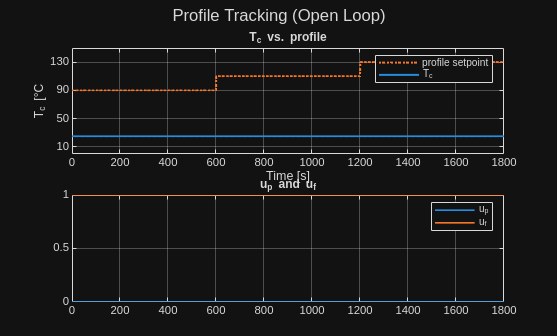

% initialization points
sim_params.T_c_start = p.T_amb;
sim_params.m_p_start = 10000;
% linearization and timeseries
sim_params.t_min = 0;
sim_params.t_max = 1800;
sim_params.lin = linearize(p, [0.4; 0.6]);
% noise parameters
sim_params.noise_bandwidth = 100; % Hz
sim_params.noise_amplitude = 0.01; % normal to y
T_c_set_series = @(t) (t<=600)*90+((t>600).*(t<=1200))*110+(t>1200)*130;
sim_params.setpoint = @(t) [Tce2Tfe(p,T_c_set_series(t)); T_c_set_series(t); 0];
sim_params.door_status = @(t) 0; % never

% Simulation for Profile Tracking
[sat.t, sat.x_aug, sat.u] = run_simulation(p, sim_params, @integral_only, @open_loop);

% plot
figure;
sgtitle("Profile Tracking (Open Loop)")
subplot(2,1,1);
plot(sat.t,   sat.x_aug(2,:),   'LineWidth', 1.5); hold on;
set = T_c_set_series(sat.t);
h2 = plot(sat.t,set,   'LineWidth', 1.5, 'LineStyle', ':');
uistack(h2, 'bottom');
legend('profile setpoint', 'T_c')
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C']);
title('T_c vs. profile');
yticks([10 50 90 130]);
xlim([0 1800])
grid on;
subplot(2,1,2);
plot(sat.t, sat.u(1,:), 'LineWidth', 1.2); hold on;
plot(sat.t, sat.u(2,:), 'LineWidth', 1.2);
title('u_p and u_f');
legend('u_p','u_f');
xlim([0 1800])
grid on;

## Profile Tracking (PI Controller)

% initialization points
sim_params.T_c_start = p.T_amb;
sim_params.m_p_start = 10000;
% linearization and timeseries
sim_params.t_min = 0;
sim_params.t_max = 1800;
sim_params.lin = linearize(p, [0.4; 0.6]);
% noise parameters
sim_params.noise_bandwidth = 100; % Hz
sim_params.noise_amplitude = 0.01; % normal to y
T_c_set_series = @(t) (t<=600)*90+((t>600).*(t<=1200))*110+(t>1200)*130;
sim_params.setpoint = @(t) [Tce2Tfe(p,T_c_set_series(t)); T_c_set_series(t); 0];
sim_params.door_status = @(t) 0; % never

% Simulation for Profile Tracking
[sat.t, sat.x_aug, sat.u] = run_simulation(p, sim_params, @integral_only, @PI_feedback);

% plot
figure;
sgtitle("Profile Tracking (Open Loop)")
subplot(2,1,1);
plot(sat.t,   sat.x_aug(2,:),   'LineWidth', 1.5); hold on;
set = T_c_set_series(sat.t);
h2 = plot(sat.t,set,   'LineWidth', 1.5, 'LineStyle', ':');
uistack(h2, 'bottom');
legend('profile setpoint', 'T_c')
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C']);
title('T_c vs. profile');
yticks([10 50 90 130]);
xlim([0 1800])
grid on;
subplot(2,1,2);
plot(sat.t, sat.u(1,:), 'LineWidth', 1.2); hold on;
plot(sat.t, sat.u(2,:), 'LineWidth', 1.2);
title('u_p and u_f');
legend('u_p','u_f');
xlim([0 1800])
grid on;

## Profile Tracking (PI Controller)

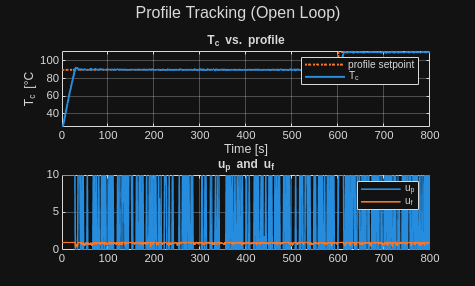

% initialization points
sim_params.T_c_start = p.T_amb;
sim_params.m_p_start = 10000;
sim_params.time_resolution = 1;
% linearization and timeseries
sim_params.t_min = 0;
sim_params.t_max = 800;
sim_params.lin = linearize(p, [0.4; 0.6]);
% noise parameters
sim_params.noise_bandwidth = 100; % Hz
sim_params.noise_amplitude = 0.01; % normal to y
T_c_set_series = @(t) (t<=600)*90+((t>600).*(t<=1200))*110+(t>1200)*130;
sim_params.setpoint = @(t) [Tce2Tfsim_params.input = @(t) t<0; % nonee(p,T_c_set_series(t)); T_c_set_series(t); 0];
sim_params.door_status = @(t) t<0; % (t>120).*(t<150); % never


% Simulation for Profile Tracking
[sat.t, sat.x_aug, sat.u] = run_simulation(p, sim_params, @saturating_integral_only, @PI_feedback);

% plot
figure;
sgtitle("Profile Tracking (Open Loop)")
subplot(2,1,1);
plot(sat.t,   sat.x_aug(2,:),   'LineWidth', 1.5); hold on;
set = T_c_set_series(sat.t);
h2 = plot(sat.t,set,   'LineWidth', 1.5, 'LineStyle', ':');
uistack(h2, 'bottom');
legend('profile setpoint', 'T_c')
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C']);
title('T_c vs. profile');
%yticks([10 50 90 130]);
xlim([sim_params.t_min sim_params.t_max])
grid on;
subplot(2,1,2);
plot(sat.t, sat.u(1,:), 'LineWidth', 1.2); hold on;
plot(sat.t, sat.u(2,:), 'LineWidth', 1.2);
title('u_p and u_f');
legend('u_p','u_f');
xlim([sim_params.t_min sim_params.t_max])
grid on;

## checking out noise

noise_bandwidth = 10; % Hz
noise_amplitude = 0.1; % normalized to y
t_min = sim_params.t_min;
t_max = sim_params.t_max;
noise_times = linspace(t_min, t_max, (t_max-t_min)*noise_bandwidth);
noise_values = noise_amplitude*randn(size(noise_times));
noise = @(t) interp1(noise_times, noise_values, t); % 1000 Hz sampling rate of the measuring device, let's say

## Test

size(sim_params.setpoint(1))
feed_struct.x_hat = x_hat;
feed_struct.x_I = 3;
feed_struct.lin = lin;
feed_struct.setpoint = setpoint;
feed_struct.y = 3;
saturate(feedback_wrapper(@integral_feedback, feed_struct)+op_point2u(p,setpoint(1)), [p.u_p_max; p.u_f_max], [p.u_p_min; p.u_f_min])

## Open-Loop Transfer Function

% initialization points
sim_params.T_c_start = p.T_amb; % start at the setpoint later
sim_params.m_p_start = 10000;
% linearization and timeseries
sim_params.t_min = 0;
sim_params.t_max = 1800;
sim_params.lin = linearize(p, [0.4; 0.6]);

% define r (setpoint) as a noise spectrum timeseries
r_bandwidth = 500; % Hz
r_amplitude = 200; % normalized to y
r_times = linspace(sim_params.t_min, sim_params.t_max, (sim_params.t_max-sim_params.t_min)*r_bandwidth);
r_values = r_amplitude*randn(size(r_times));
% allows run_simulation to define an anonymous function for setpoint

% noise parameters
sim_params.noise_bandwidth = 100; % Hz
sim_params.noise_amplitude = 0.01; % normal to y
%sim_params.setpoint_times = r_times; % special (allows setpoint to be an anonymous function)
%sim_params.setpoint_values = r_values; % special (allows setpoint to be an anonymous function)
% do not define sim_params.setpoint explicitly
T_c_set_series = @(t) 80+40*sin(0.01*t);%interp1(r_times,r_values,t);
sim_params.setpoint = @(t) [Tce2Tfe(p,T_c_set_series(t)); T_c_set_series(t); 0];
sim_params.door_status = @(t) 0 % never

sim_params = struct with fields:
          T_c_start: 25
          m_p_start: 10000
              t_min: 0
              t_max: 1800
                lin: [1×1 struct]
    noise_bandwidth: 100
    noise_amplitude: 0.0100
           setpoint: @(t)[Tce2Tfe(p,T_c_set_series(t));T_c_set_series(t);0]
        door_status: @(t)0



% Simulation for Profile Tracking
[sat.t, sat.x_aug, sat.u] = run_simulation(p, sim_params, @saturating_integral_observer, @basic_feedback);

% plot
figure;
sgtitle("Profile Tracking (Saturating Integral)")
subplot(2,1,1);
plot(sat.t,   sat.x_aug(2,:),   'LineWidth', 1.5); hold on;
set = T_c_set_series(sat.t);
h2 = plot(sat.t,set,   'LineWidth', 1.5, 'LineStyle', ':');
uistack(h2, 'bottom');
legend('profile setpoint', 'T_c')
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C']);
title('T_c vs. profile');
yticks([10 50 90 130]);
xlim([0 1800])
grid on;
subplot(2,1,2);
plot(sat.t, sat.u(1,:), 'LineWidth', 1.2); hold on;
plot(sat.t, sat.u(2,:), 'LineWidth', 1.2);
title('u_p and u_f');
legend('u_p','u_f');
xlim([0 1800])
grid on;
clear sim_params;

## show x_hat

set = @(t) 100+40*sin(0.01*t);
figure;
plot(sat.t,   sat.x_aug(4,:),   'LineWidth', 1.5); hold on;
plot(sat.t,   sat.x_aug(1,:),   'LineWidth', 1.5); 
set = 80+40*sin(0.01*sat.t);
h2 = plot(sat.t,set,   'LineWidth', 1.5, 'LineStyle', ':');
uistack(h2, 'bottom');
legend('profile setpoint', 'T_c')
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C']);
title('T_c_ _h_a_t vs. profile');
yticks([10 50 90 130]);
xlim([0 1800])
grid on;

## Nyquist Plots

syms s
figure;
lin = linearize(p, [0.4; 0.6]);
Gsym = lin.C*inv(s*eye(3)-lin.A)*lin.B

$$Gsym = \left(\begin{array}{cc} \frac{360}{5000\,s^{2}+2050\,s+29} & \frac{240}{5000\,s^{2}+2050\,s+29} \end{array}\right)$$


Gp = tf(360, [5000 2050 29]);
P = tf(15,1);
I = tf(4,[1 0]); %I = tf(1,[30.5,0])
F = tf(0.2,1);
Gf = tf(240, [5000 2050 29]);

np = nyquistplot(P*Gp+I*Gp+F*Gf);
T = feedback(P*Gp+I*Gp+F*Gf,1);
isstable(T)

ans = logical
   1


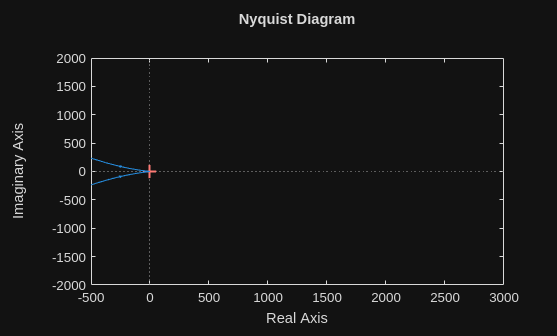

ylim([-2000,2000])
xlim([-500,3000])


colors = {
    [0.85, 0.48, 0.46];   % #D97B76
    [0.89, 0.64, 0.42];   % #E3A36A
    [0.91, 0.85, 0.48];   % #E8D97A
    [0.47, 0.73, 0.50];   % #78B97F
    [0.43, 0.64, 0.78];   % #6EA3C6
    [0.48, 0.46, 0.73];   % #7A76B9
    [0.69, 0.48, 0.74];   % #B07ABD
}; % Credit to gen AI. Convenience
weight = linspace(0.62,0.65,4);

figure;
for i = 1:4
    np = nyquistplot((weight(i))*P*Gp+I*Gp+F*(weight(i))*Gf); hold on;
end
lines = findall(gca, 'Type', 'Line');
for i = 1:4
    lines(i).Color = colors{i};
end
letters = {'a','b','c','d','e','f','g'}

letters = 1×7 cell array
    {'a'}    {'b'}    {'c'}    {'d'}    {'e'}    {'f'}    {'g'}


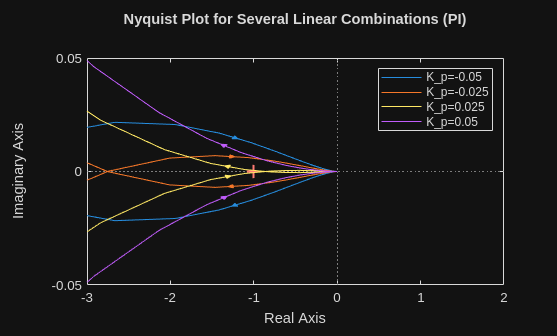

legend('K_p=-0.05','K_p=-0.025','K_p=0.025','K_p=0.05')
ylim([-0.05,0.05])
xlim([-3,2])
title("Nyquist Plot for Several Linear Combinations (PI)")


figure;
np = nyquistplot(P*Gp+I*Gp+F*Gf); hold on;
a = 0.636

a = 0.6360

0.636*15

ans = 9.5400

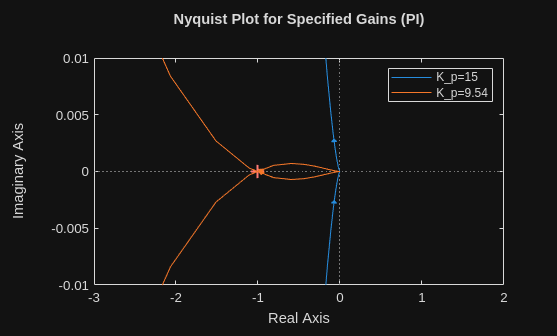

np = nyquistplot(a*P*Gp+I*Gp+F*Gf); hold on;
ylim([-0.01,0.01])
xlim([-3,2])
title("Nyquist Plot for Specified Gains (PI)")
legend('K_p=15','K_p=9.54')


%step(G)
%bode(G)

%F = tf(1,1)

subs(Gsym,s,0)

$$ans = \left(\begin{array}{cc} \frac{360}{29} & \frac{240}{29} \end{array}\right)$$


%step(H)


## pole

pole(Gp)

ans =          0
   -0.3953
   -0.0147


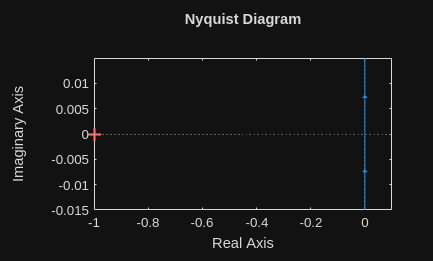

figure;
nyquistplot(tf(1,[1,0])/100);

T = feedback(1/30*Gp+1000*Gf,1);
isstable(T)

ans = logical
   1


## temp

lin = linearize(p,[0.4;0.6]);
A2 = lin.A(1:2,1:2);
B2 = lin.B(1:2,1:2);

k = [place(A2,B2,[-3.8+0.2i; -3.8-0.2i]),[0;0]]

k =     4.1481  134.3356         0
    2.7654   89.5571         0


## Quickie

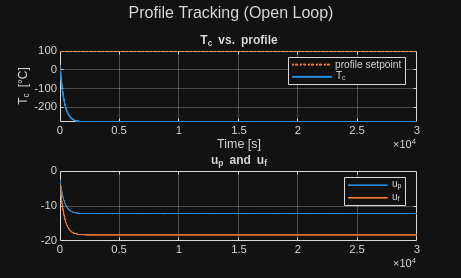

% initialization points
sim_params.T_c_start = p.T_amb;
sim_params.m_p_start = 100000;
% linearization and timeseries
sim_params.t_min = 0;
sim_params.t_max = 30000;
sim_params.lin = linearize(p, [0.4; 0.6]);
% a
a = cell(1, 2);
a{1} = "0.4";
a{2} = "0.4";
% noise parameters
sim_params.noise_bandwidth = 1; % Hz
sim_params.noise_amplitude = 0; % normal to y
T_c_set_series = @(t) (t<20000000)*100;
sim_params.setpoint = @(t) [Tce2Tfe(p,T_c_set_series(t)); T_c_set_series(t); 0];
sim_params.door_status = @(t) (t<20000000)*0; % never

% Simulation for Profile Tracking 
[sat.t, sat.x_aug, sat.u] = run_simulation(p, sim_params, @integral_only, @PI_feedback);

% plot
figure;
sgtitle("Profile Tracking (Open Loop)")
subplot(2,1,1);
plot(sat.t,   sat.x_aug(2,:),   'LineWidth', 1.5); hold on;
set = T_c_set_series(sat.t);
h2 = plot(sat.t,set,   'LineWidth', 1.5, 'LineStyle', ':');
uistack(h2, 'bottom');
legend('profile setpoint', 'T_c')
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C]']);
title('T_c vs. profile');
%yticks([10 50 90 130]);
xlim([0 sim_params.t_max])
grid on;
subplot(2,1,2);
plot(sat.t, sat.u(1,:), 'LineWidth', 1.2); hold on;
plot(sat.t, sat.u(2,:), 'LineWidth', 1.2);
title('u_p and u_f');
legend('u_p','u_f');
xlim([0 sim_params.t_max])
grid on;

size(sat.t);

## Save Results to "Stable Array"

if exist('stable_t', 'var') && exist('stable_x_aug', 'var') && exist('stable_u', 'var')
    stable_t = cat(3,stable_t, sat.t);
    stable_x_aug = cat(3,stable_x_aug, sat.x_aug);
    stable_u = cat(3, stable_u, sat.u);
    stable_sum = cat(3,stable_sum, a)
else
    stable_t = sat.t; 
    stable_x_aug = sat.x_aug; 
    stable_u = sat.u;
    stable_sum = a;
end
size(stable_t,3)

ans = 1

## Save Results to "Unstable Array"

if exist('unstable_t', 'var') && exist('unstable_x_aug', 'var') && exist('unstable_u', 'var')
    unstable_t = cat(3,unstable_t, sat.t);
    unstable_x_aug = cat(3,unstable_x_aug, sat.x_aug);
    unstable_u = cat(3, unstable_u, sat.u);
    unstable_sum = cat(3,unstable_sum, a);
else
    unstable_t = sat.t; 
    unstable_x_aug = sat.x_aug; 
    unstable_u = sat.u;
    unstable_sum = a;
end
size(unstable_t,3)

ans = 2

## Custom edit

stable_t(:,:,3) = sat.t; 
stable_x_aug(:,:,3) = sat.x_aug; 
stable_u(:,:,3) = sat.u;
stable_sum(:,:,3) = a;

## Plot Stability (Single Comparison -- needs changes to function as intended)

figure; 
sgtitle("Single-Feedback Stability near K_c_r_i_t")
subplot(2,1,1);
hold on;
N = size(stable_t,3);
legend_entries = cell(1, N);
size(stable_sum)

ans =      1     2     3


for k = 1:N
    plot(stable_t(:,:,k),stable_x_aug(2,:,k),   'LineWidth', 1.5);
    legend_entries{k} = sprintf("Line (%s,%s)", stable_sum{1,1,k}, stable_sum{1,2,k});
end


%plot(past_t, past_x_aug(2,:),   'LineWidth', 1.5);
set = T_c_set_series(sat.t);
%h2 = plot(sat.t,set,   'LineWidth', 1.5, 'LineStyle', ':');
%uistack(h2, 'bottom');
legend(legend_entries);%   Σa_i');
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C]']);
title('Stable Feedback Predicted (K∈K_s_t_a_b_l_e)');
%yticks([10 50 90 130]);
xlim([0 sim_params.t_max])
grid on;


subplot(2,1,2);
%plot(sat.t, sat.u(1,:), 'LineWidth', 1.2); hold on;
%plot(past_t, past_u(1,:), 'LineWidth', 1.2);
RGB = orderedcolors("gem");
rgb2hex(RGB)

ans = 7×1 string array
    "#1171BE"
    "#DD5400"
    "#EDB120"
    "#8516D1"
    "#3BAA32"
    "#2FBEEF"
    "#D1048B"


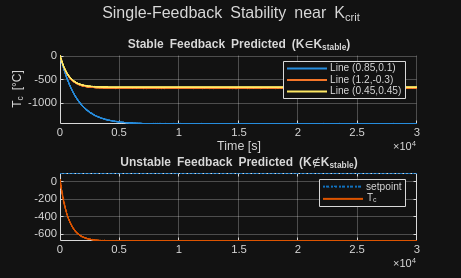

plot(past_t, past_x_aug(2,:),   'LineWidth', 1.5, 'Color', '#DD5400'); hold on;
h2 = plot(sat.t,set,   'LineWidth', 1.5, 'LineStyle', ':', 'Color', '#1171BE');
uistack(h2, 'bottom');
title('Unstable Feedback Predicted (K∉K_s_t_a_b_l_e)');
legend('setpoint', 'T_c');
xlim([0 sim_params.t_max])
grid on;

## Plot Stability (Multiple Runs)

figure; 
%sgtitle("Multi-Feedback Stability near Σa_i=1")
sgtitle("Integral Feedback Stability (Integral Saturation)")

% STABLE
subplot(2,1,1);
hold on;
N = size(stable_t,3);
%legend_entries = cell(1, N);
size(stable_sum)

ans =      1     2


for k = 1:N
    plot(stable_t(:,:,k),stable_x_aug(2,:,k),   'LineWidth', 1.5);
    %legend_entries{k} = sprintf("a = [%s,%s]", stable_sum{1,1,k}, stable_sum{1,2,k});
end
%legend(legend_entries);
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C]']);
%title('Stable Feedback Predicted (Σa_i<1)');
title('Stable Feedback Predicted (K_i<K_c_r_i_t_,_i)');
xlim([0 sim_params.t_max])
grid on;

% UNSTABLE
subplot(2,1,2);
hold on;
N = size(unstable_t,3);
legend_entries = cell(1, N);
size(stable_sum)

ans =      1     2


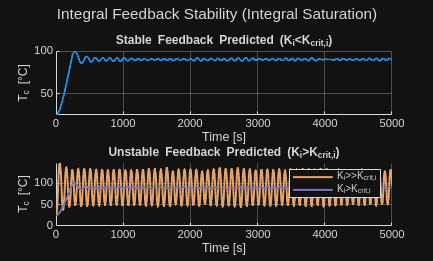

colors = {
    [0.89, 0.64, 0.42];   % #E3A36A
    [0.48, 0.46, 0.73];   % #7A76B9
    [0.69, 0.48, 0.74];   % #B07ABD
};
for k = 1:N
    plot(unstable_t(:,:,k),unstable_x_aug(2,:,k),   'LineWidth', 1.5, 'Color', colors{k});
    %legend_entries{k} = sprintf("a = [%s,%s]", unstable_sum{1,1,k}, unstable_sum{1,2,k});
end

%legend(legend_entries);
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C]']);
legend('K_i>>K_c_r_i_t_,_i', 'K_i>K_c_r_i_t_,_i')
%title('Unstable Feedback Predicted (Σa_i>1)');
title('Unstable Feedback Predicted (K_i>K_c_r_i_t_,_i)');
xlim([0 sim_params.t_max])
%ylim([-2000000000000, 40]);
grid on;

## simplify fraction

numer = 240;
denom = 5000;

f = sym(numer)/sym(denom);   % convert to symbolic
f_simplified = simplify(f)

$$f\_simplified = \frac{6}{125}$$

u = 1; y = 1; u_p = 1;

sys = @(s) tf(360,)

Unexpected ')'. Remove trailing comma or add an expression after the comma.

sys = function_handle with value:
    @(s)G


sys = function_handle with value:
    @(s)G


## set

figure;
sgtitle("Profile Tracking (Open Loop)")
subplot(2,1,1);
plot(sat.t,   sat.x_aug(1,:),   'LineWidth', 1.5); hold on; %
plot(sat.t,   sat.x_aug(2,:),   'LineWidth', 1.5); %
plot(sat.t,   sat.x_aug(4,:),   'LineWidth', 1.5); %
plot(sat.t,   sat.x_aug(5,:),   'LineWidth', 1.5); %
set = T_c_set_series(sat.t.');
size(set)

ans =      1   905


%h2 = plot(sat.t,set,   'LineWidth', 1.5, 'LineStyle', ':'); %
%uistack(h2, 'bottom');
%legend('profile setpoint', 'T_c')
legend('Tf','Tc','Tfh','Tch')%,'setpoint')
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C]']);
title('T_c vs. profile');
yticks([10 50 90 130]);
xlim([0 1800])
grid on;


subplot(2,1,2);
plot(sat.t, sat.u(1,:), 'LineWidth', 1.2); hold on;
plot(sat.t, sat.u(2,:), 'LineWidth', 1.2);
title('u_p and u_f');
legend('u_p','u_f');
xlim([0 1800])
grid on;

## Create a Sample of the Spectrum

% initialization points
sim_params.T_c_start = 29.95; % start at the setpoint later
sim_params.m_p_start = 10000;
sim_params.time_resolution = 2;
% linearization and timeseries
sim_params.t_min = 0;
sim_params.t_max = 3000;
sim_params.lin = linearize(p, [0.4; 0.6]);

% noise parameters
sim_params.noise_bandwidth = 0.01; % Hz
sim_params.noise_amplitude = 0; % normal to y

% no setpoint, raw input for open loop, no change in door status
sim_params.setpoint = @(t) [0;0;0]; % none
sim_params.input = @(t) [cos(10*2*pi*t);0.6];
sim_params.door_status = @(t) 0 % never

sim_params = struct with fields:
          T_c_start: 29.9500
          m_p_start: 10000
    time_resolution: 2
              t_min: 0
              t_max: 3000
                lin: [1×1 struct]
    noise_bandwidth: 0.0100
    noise_amplitude: 0
           setpoint: @(t)[0;0;0]
              input: @(t)[cos(10*2*pi*t);0.6]
        door_status: @(t)0


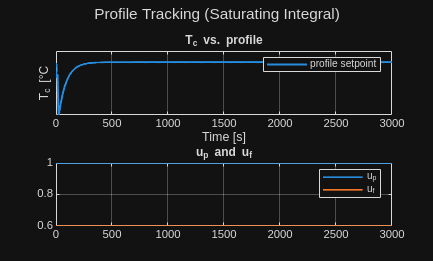


% simulation
[sat.t, sat.x_aug, sat.u] = run_simulation(p, sim_params, @integral_only, @open_loop);

## Save Results to Samples Array (Samples of Spectrum)

if exist('samples_t', 'var') && exist('samples_x_aug', 'var') && exist('samples_u', 'var')
    samples_t = cat(3,samples_t, sat.t);
    samples_x_aug = cat(3,samples_x_aug, sat.x_aug);
    samples_u = cat(3, samples_u, sat.u);
else
    samples_t = sat.t; 
    samples_x_aug = sat.x_aug; 
    samples_u = sat.u;
end
size(samples_t,3)

ans = 16

ans = 2

## Plot Spectrum, Samples

% Post-Processing
input_coefficients = fftshift(fft(sat.u(1,2*round(0.1*size(sat.t,1))+1:size(sat.t,1))));

Unable to resolve the name 'sat.u'.

output_coefficients = fftshift(fft(sat.x_aug(2,2*round(0.1*size(sat.t,1))+1:size(sat.t,1))));
output_coefficients(901) = 0;
transfer_noise = output_coefficients./input_coefficients;
frequencies = linspace(-0.5/sim_params.time_resolution, ...
                               0.5/sim_params.time_resolution, ...
                               size(sat.t,1)-2*round(0.1*size(sat.t,1)));

% set val at zero to zero. We won't worry about offsets here, but that makes this value invalid
output_coefficients(round(size(frequencies,2)/2)) = 0; 

% Proper transfer function
G = @(s) 360./(5000*s.^2+2050*s+29)

s = linspace(-0.5/sim_params.time_resolution,0.5/sim_params.time_resolution,10001);
figure;
subplot(2,1,1);
plot(s,abs(G(1i*2*pi*s))); hold on;
title("Magnitude")
subplot(2,1,2);
plot(s,angle(G(1i*2*pi*s))); hold on;
frequencies = linspace(-0.5/sim_params.time_resolution, ...
                               0.5/sim_params.time_resolution, ...
                               size(samples_t,1)-2*round(0.1*size(samples_t,1)));
for i = 1:size(samples_t,3)
    if i ~= 2
        subplot(2,1,1);
        input_coefficients(:,:,i) = fftshift(fft(samples_u(1,2*round(0.1*size(samples_t,1))+1:size(samples_t,1),i)));
        output_coefficients(:,:,i) = fftshift(fft(samples_x_aug(2,2*round(0.1*size(samples_t,1))+1:size(samples_t,1),i)));
        hold on;
        loglog(frequencies,abs(output_coefficients(:,:,i)./input_coefficients(:,:,i)).*(abs(input_coefficients(:,:,i))>100)+0.01, 'Color', '#E09060');
        subplot(2,1,2);
        hold on;
        semilogx(frequencies,angle(output_coefficients(:,:,i)./input_coefficients(:,:,i)).*(abs(input_coefficients(:,:,i))>100), 'Color', '#E09060');
    end
end
frequencies_2 = linspace(-0.5/sim_params.time_resolution, ...
                               0.5/sim_params.time_resolution, ...
                               size(samples_2_t,1)-2*round(0.1*size(samples_2_t,1)));
title("Phase")
legend('Predicted','Samples')
xlabel('Input Frequency (Hz)')
set(gca, 'XScale', 'log', 'YScale', 'lin')
xlabel('Frequency (Hz)')
ylabel('Phase (rad)')
subplot(2,1,1)
set(gca, 'XScale', 'log', 'YScale', 'log')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
legend('Predicted','Samples')
figure;
s = linspace(0,10,1000000);
plot(s,angle(G(1i*2*pi*s))); hold on;
set(gca, 'XScale', 'log', 'YScale', 'lin')
xlabel('Frequency (Hz)')
ylabel('Phase (rad)')